# Methods - Trajectory Planning

Here we will describe our approach to trajectory planning for the ice-cream dispensing robot arm. There are a maximum of 6 desired end-effector points: home, cone dispenser, flavor 1, flavor 2, flavor 3, and customer drop-off. Each cycle begins with the end-effector at the home config, then cone dispenser, a combination of flavors, customer drop-off, and then back at home. This simplifies our trajectory planning problem since some paths repeat every cycle. 

The steps for trajectory planning are given as follows:

- Use numerical inverse kinematics to find singularity-free joint angles that correspond to the end-effector at each of the 6 points.

- Generate a singularity-free minimum time trajectory from home to cone dispenser and from customer drop-off to home.

- Depending on customer choice of flavors, generate singularity-free minimum time trajectories from cone dispenser to first flavor, between flavors, and then to customer drop-off.

- Combine trajectories in correct order and execute motion.

- Repeat steps 3-4 for next cycle depending on customer input.

We use a minimum-time trajectory to optimize the cycle time. Given a constant acceleration, this specifies the shortest trajectory time by starting the trajectory at maximum acceleration ($+\alpha$) until an appropriate switching time, at which point we instantly switch to minimum acceleration ($-\alpha$). Since each trajectory requires zero velocity at the beginning and end, the switching time occurs at half the total trajectory time. Let $t_0$ be the start time and $t_f$ be the end time of the trajectory. We know from trajectory symmetry that the switching time $t_s =\frac{t_f -t_0 }{2}$. Let the velocity at the switching time be $V_s$ and for constant acceleration, we have $V_s =\alpha t_s$. Let $q_0$ and $q_f$ be the initial and final configuration. At the switching time, we have: $V_s =\frac{q_f -q_0 }{t_s }=\alpha t_s \;$. This leads to $t_s =\sqrt{\frac{q_f -q_0 }{\alpha }}$. 

We consider a simple example where we are asked to find a trajectory from home configuration $\theta_1 =0$ to a desired configuration $\theta_1 =\frac{\pi }{2}$ within 5 sec with a maximum joint angle acceleration $\alpha =20\;\frac{\deg }{s^2 }$. We can treat each joint motion as an independent trajectory, so this method can scale for other joints as well. The trajectory needs to be checked to ensure no singularities are crossed (described earlier, but not considered in this example). 

For $\theta_1$, $t_s =\sqrt{\frac{q_f -q_0 }{\alpha }}=\sqrt{\frac{\frac{\pi }{2}-0}{20}}=2\ldotp 12\;\sec$, which leads to $t_f =4\ldotp 24\;\sec$ (within our 5 sec specification). The angular velocity of joint 1 in the accelerating segment of the trajectory is simply given by $V_1 =\alpha t$, leading to joint angle equation of $\theta_1 =\frac{\alpha t^2 }{2}$. For the decelerating segment, the angular velocity of joint 1 is given by $V_1 =V_s -\alpha \left(t-t_s \right)=\alpha t_s -\alpha \left(t-t_s \right)=2\alpha t_s -\alpha t$. Integrating this with the appropriate initial condition leads to $\theta_1 =$$-\frac{\alpha t^2 }{2}+2\alpha t_s t^2 -\alpha t_s^2$. We can plot the angular position and velocity profiles below:

figure
qs=0; qf=pi/2; alpha=deg2rad(20);
ts=sqrt((qf-qs)/alpha);
interval=20;
t1=linspace(0,ts,interval);
t2=linspace(ts,2*ts,interval);
ang_pos1 = 0.5*alpha*t1.^2;
ang_pos2 = -0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2;
ang_vel1 = alpha*t1;
ang_vel2 = 2*alpha*ts - alpha*t2;
t=[t1,t2];
ang_pos=rad2deg([ang_pos1,ang_pos2]);
vel_pos=rad2deg([ang_vel1,ang_vel2]);
subplot(1,2,1)
plot(t,ang_pos); xlabel('Time (sec)'); ylabel('Angular position (deg)')
subplot(1,2,2)
plot(t,vel_pos); xlabel('Time (sec)'); ylabel('Angular velocity (deg/sec)')

The trajectory generated matches our desired specification. The velocity profile is piece-wise linear and changes slope at the switching time. The angular position accelerates and decelerates in a smooth motion. We can visualize $\theta_1$ in the ice-cream robot following this motion as follows:

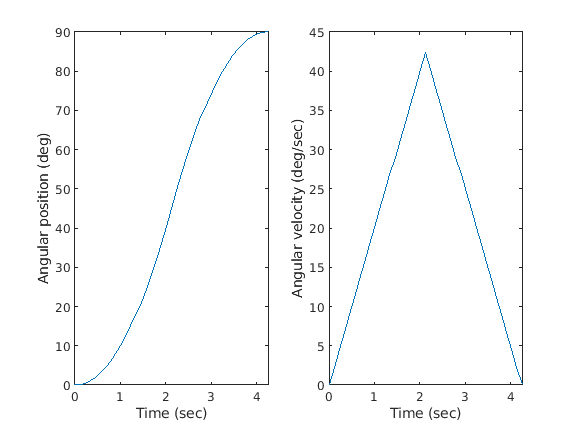

figure
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;
theta1_vec = deg2rad(ang_pos);
for i=1:length(theta1_vec)
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    theta1=theta1_vec(i); 

    theta_vec = [theta1, 0 + pi/2, 0 - pi/2 - gamma, 0];
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    plot_link(P_vec,i,length(theta1_vec));
end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Ice-cream dispensing robot following minimum time trajectory')

We can see the end-effector points are spaced tighter at the beginning and end and looser in the middle of the motion, indicating the accelerating and decelerating motion. 

## Appendix

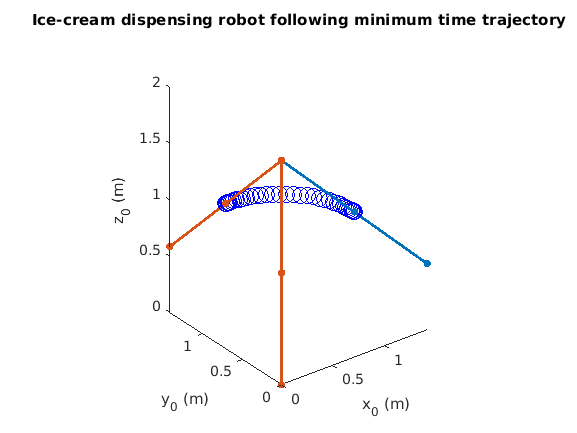

function [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec)
% Author: Nithin Kumar
% Date: 3/18/2021
% This function calculates the homogeneous transformation matrix H using DH
% convention input parameters and outputs the final H^0_n, the position of all frames
% (P_vec), and all the H matrices.
H=eye(4);
P = [0;0;0;1];
P_vec = zeros(4,length(a_vec));

    for i=1:length(a_vec)
        a=a_vec(i); d=d_vec(i); alpha=alpha_vec(i); theta=theta_vec(i);
        H_tmp = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta); ...
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta); ...
        0, sin(alpha), cos(alpha), d; ...
        0, 0, 0, 1];
       
        H=H*H_tmp;
        All_H(:,:,i) = H;
        P_vec(1:4,i) = H*P;
    end
end

function plot_link(P_vec,current,end_condition)
% This function plots each link with input P_vec that describes the origin
% of each frame.
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    h1=plot3(A,B,C,'.-','MarkerSize',12,'LineWidth',2);
    hold on
    h2=plot3(P_vec(1,3),P_vec(2,3),P_vec(3,3),'bo','MarkerSize',12);
    axis equal
    pause(0.05)
    if current~=end_condition && current~=1
        delete(h1)
    end
    
end